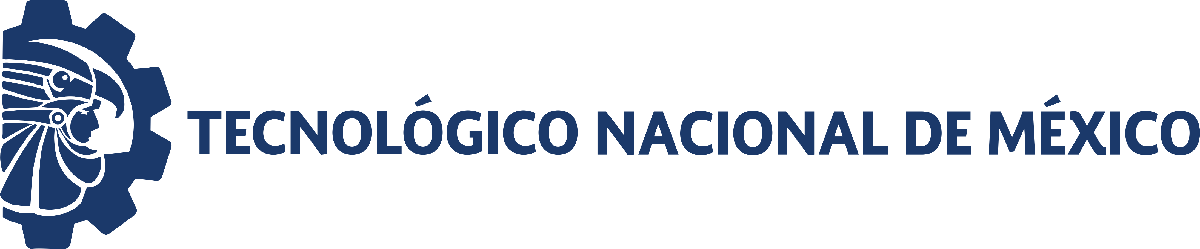                                 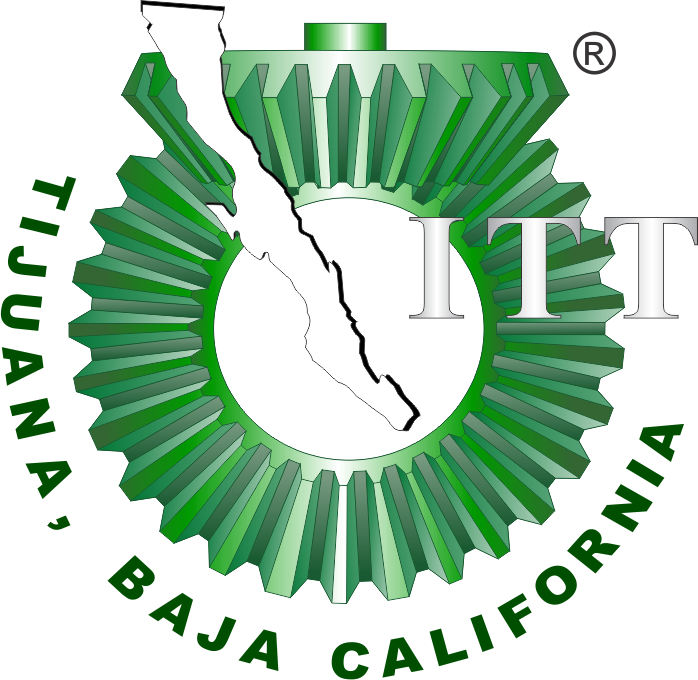

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Práctica 5: Análisis de sistemas biológicos

## Información general

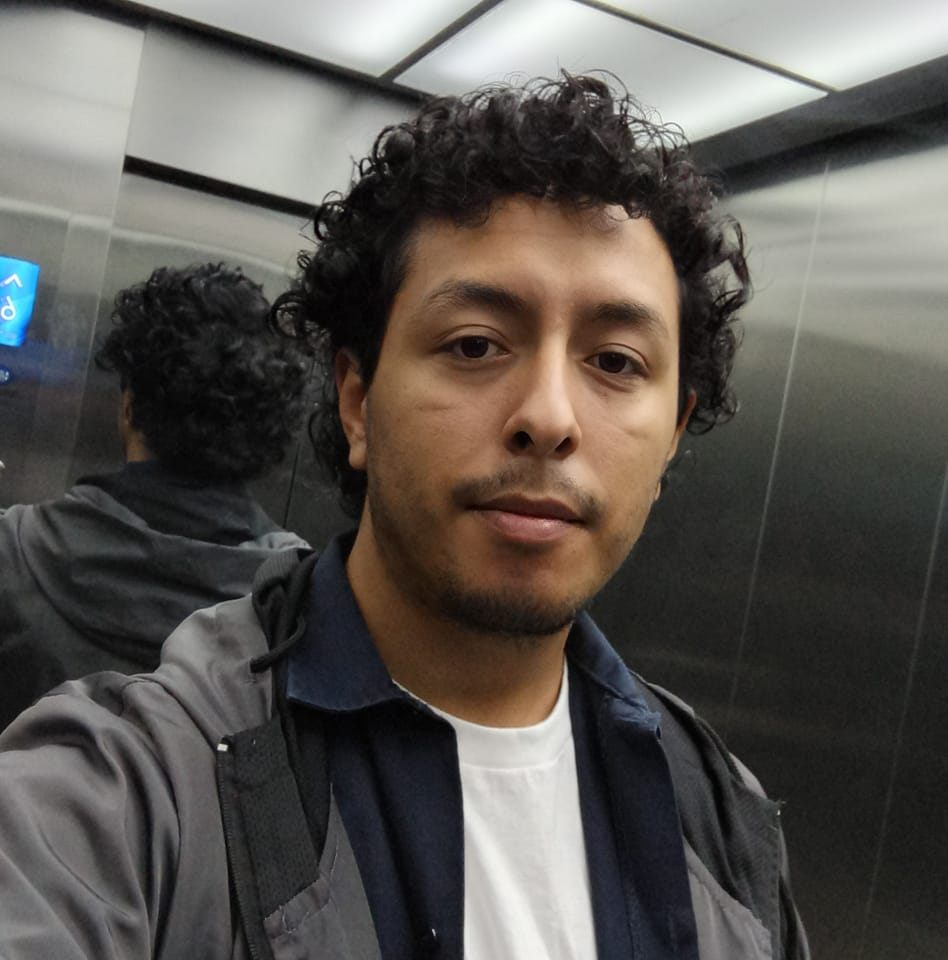

Nombre del alumno: **Cipriano Camacho Mario Tolentino**

Número de control: **20211961**

Correo institucional: **l20211961@tectijuana.edu.mx**

Carrera: **Ingenieria Biomedica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

**Objetivo:** Construir y analizar un modelo mecanicista sobre de la din·mica entre dos variables biológicas.

## Simulation data

%Datos de la simulación
clc; clear; close all; warning('off','all')
r1 = 1; b1 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21= 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
P = [r1,b1,a13,r2,b2,a21,r3,a31,d3];
a12 = [1,0.9,0.8,0.75,0.5]; 
rhoi = 0;
dt = 1E-2; 
tend = [1500,400,600,600,500];
x0 = [0.555,0.254781,0.2,0.4,0.5]; 
y0 = [0.148,0.115167,0.6,0.2,0.5]; 
z0 = [0.172,0.600527,0.1,0.4,0.4];

## Chaotic atractor [normalized]

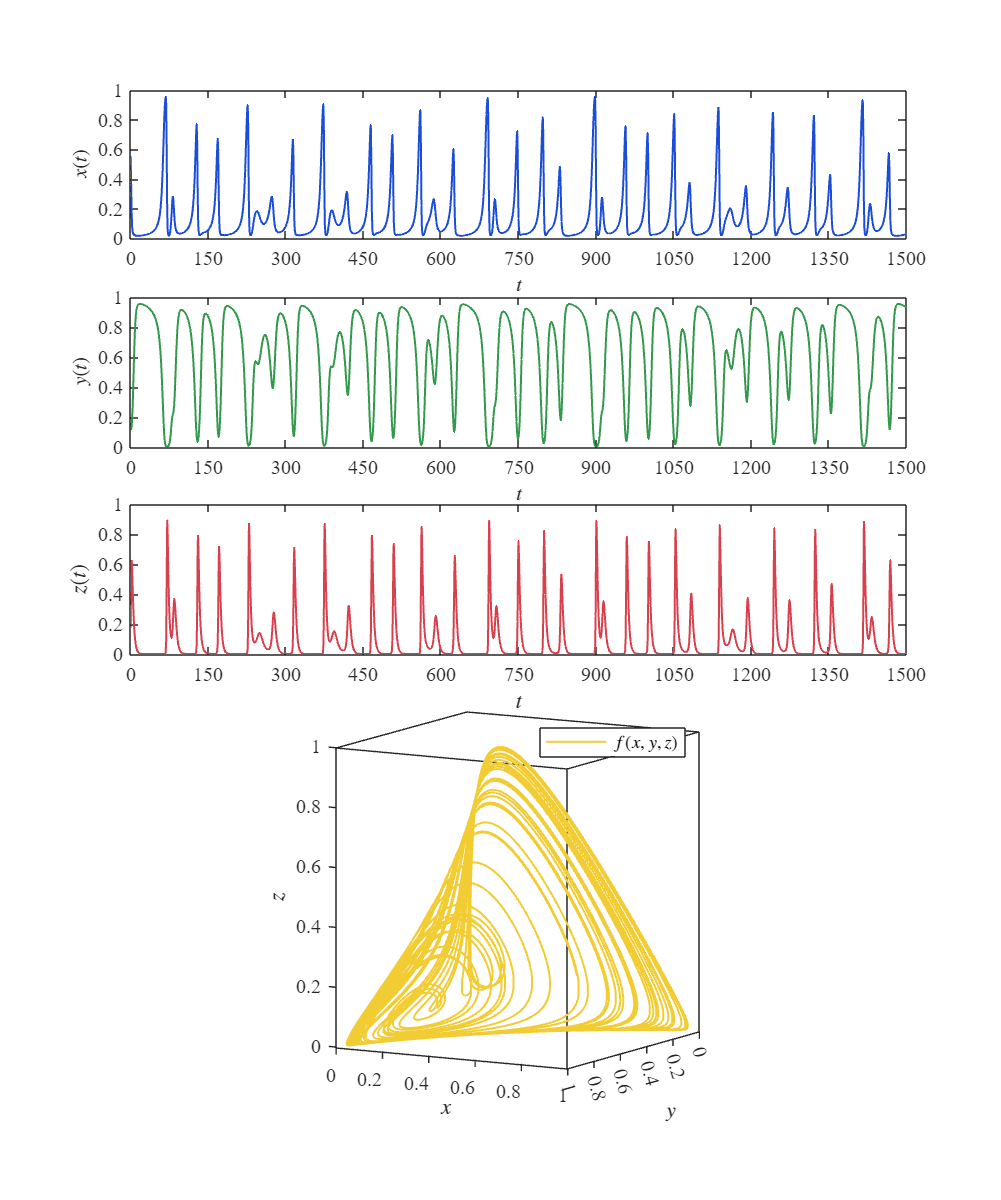

i = 1;
[t,x,y,z] = system(x0(i),y0(i),z0(i),P,a12(i),rhoi,dt,tend(i));
plotEDOs(t,x,y,z);

% exportgraphics(gcf,'1. Chaotic atractor [normalized].pdf','ContentType','Vector')

## Periodic orbit [normalized]

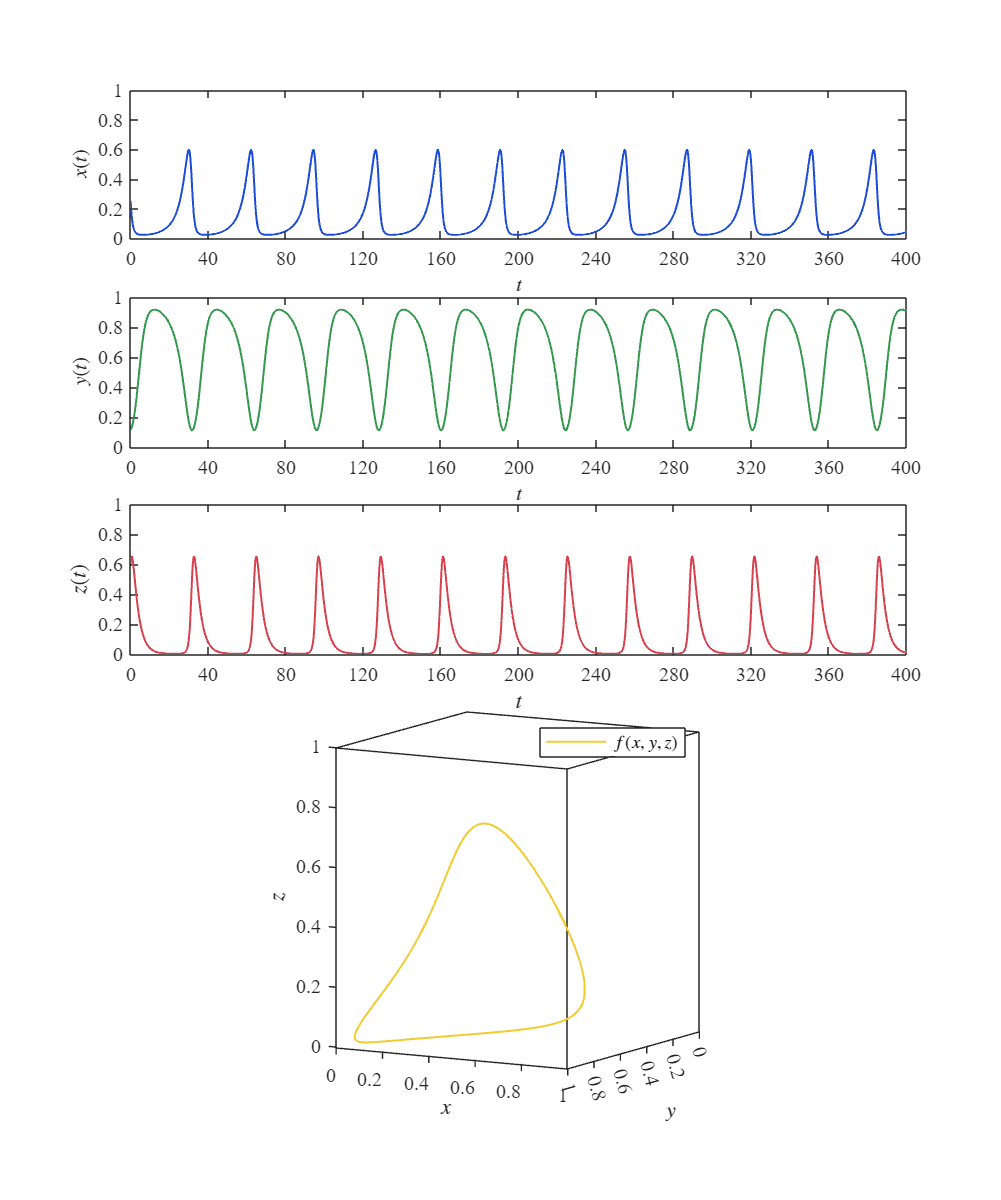

i = 2;
[t,x,y,z] = system(x0(i),y0(i),z0(i),P,a12(i),rhoi,dt,tend(i));
plotEDOs(t,x,y,z);

% exportgraphics(gcf,'2. Periodic orbit [normalized].pdf','ContentType','Vector')

## Limit cycle internal [normalized]

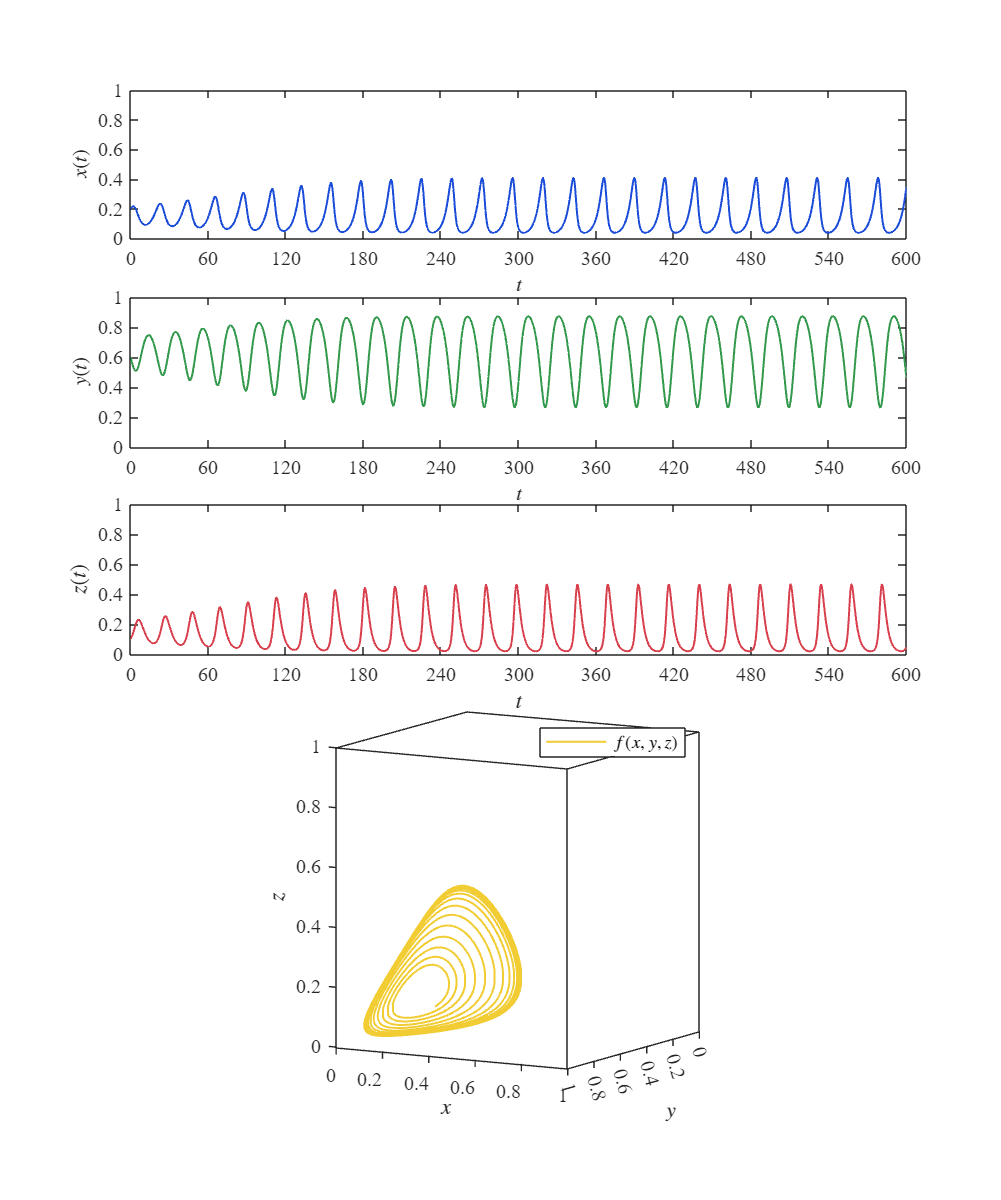

i = 3;
[t,x,y,z] = system(x0(i),y0(i),z0(i),P,a12(i),rhoi,dt,tend(i));
plotEDOs(t,x,y,z);

% exportgraphics(gcf,'3. Limit cycle internal [normalized].pdf','ContentType','Vector')

## Limit cycle external [normalized]

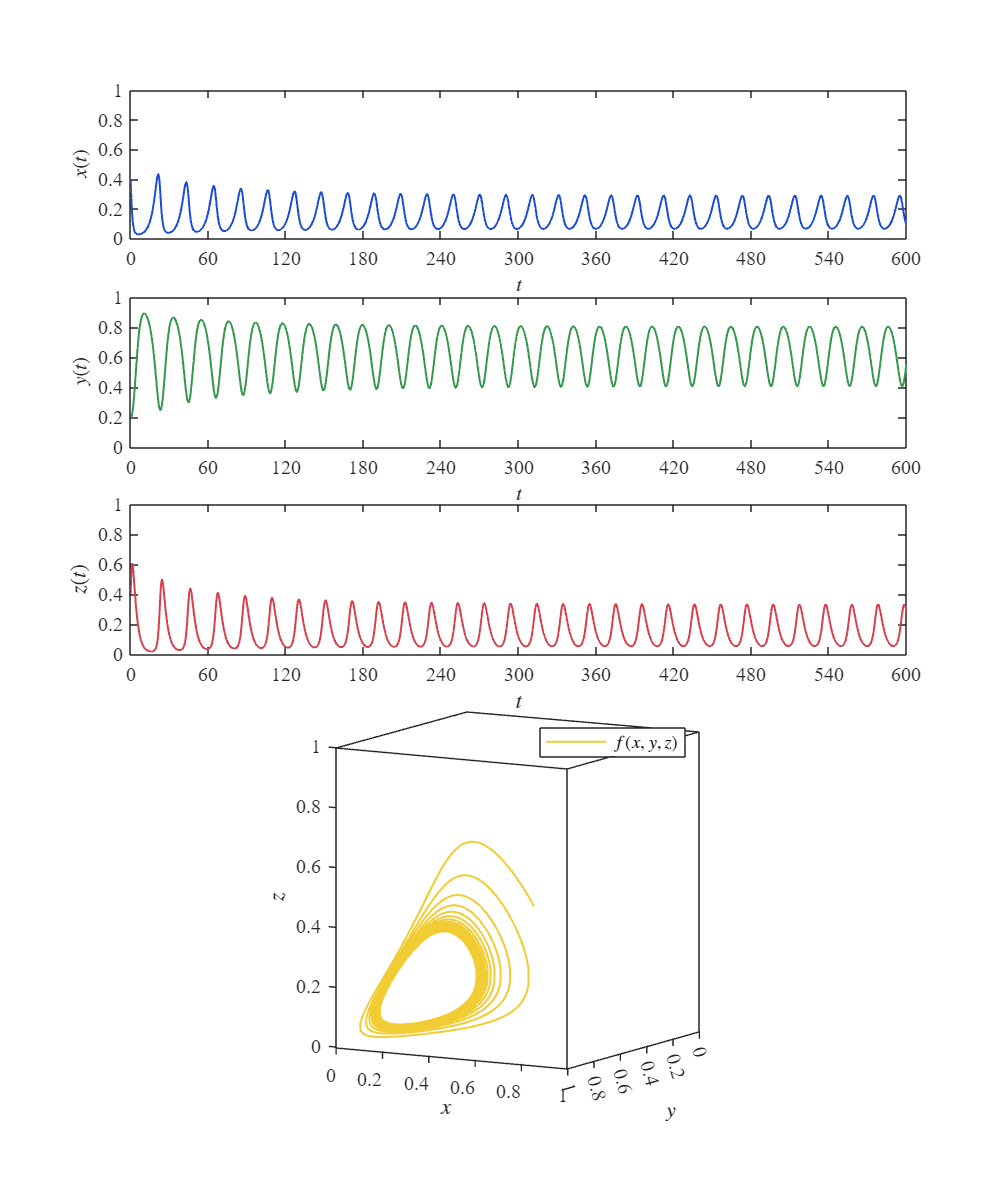

i = 4;
[t,x,y,z] = system(x0(i),y0(i),z0(i),P,a12(i),rhoi,dt,tend(i));
plotEDOs(t,x,y,z);

% exportgraphics(gcf,'4. Limit cycle external [normalized].pdf','ContentType','Vector')

## Equilibrium point [normalized]

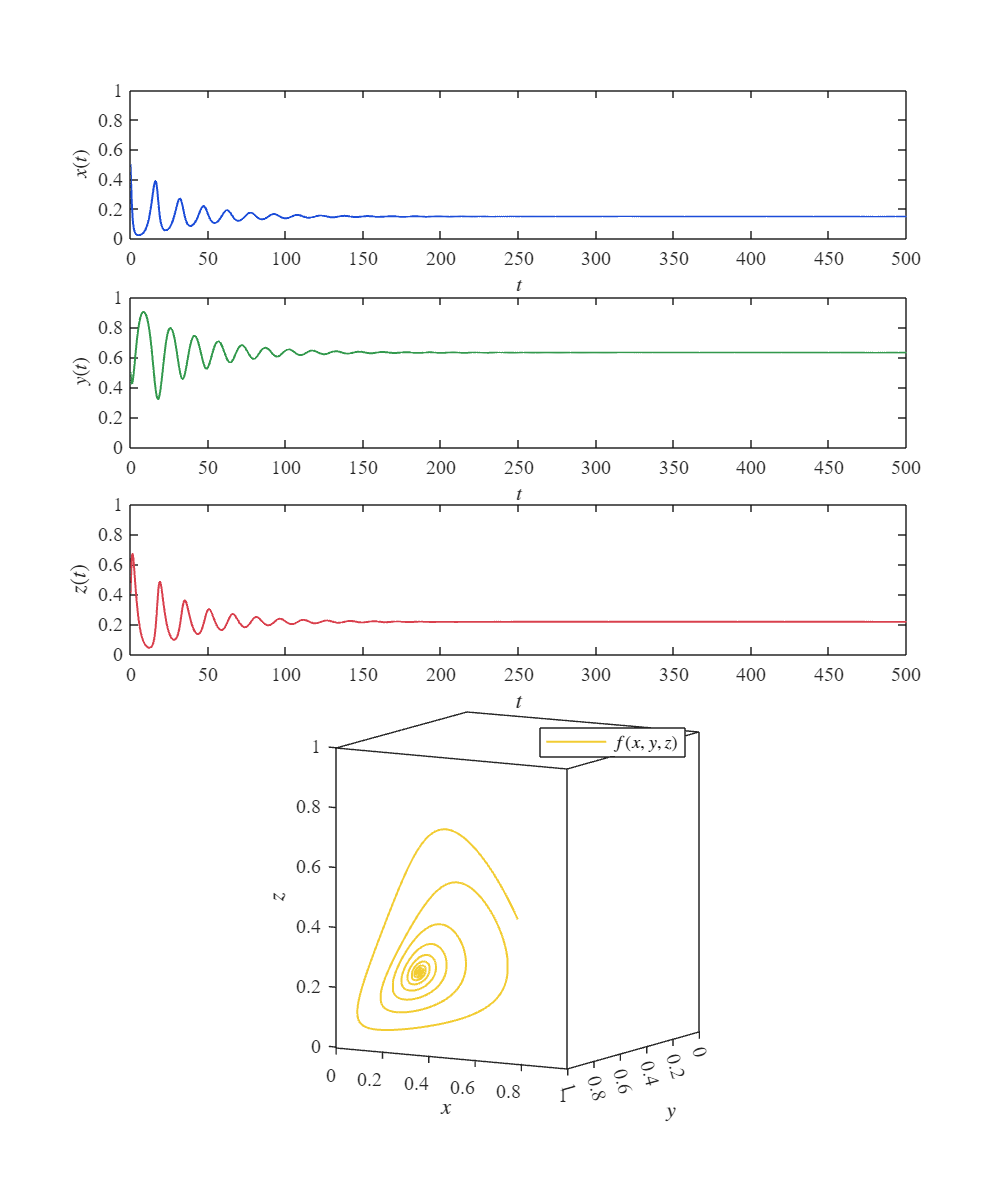

i = 5;
[t,x,y,z] = system(x0(i),y0(i),z0(i),P,a12(i),rhoi,dt,tend(i));
plotEDOs(t,x,y,z);

% exportgraphics(gcf,'5. Equilibrium point [normalized].pdf','ContentType','Vector')

## Equilibrium point [no-normalized]

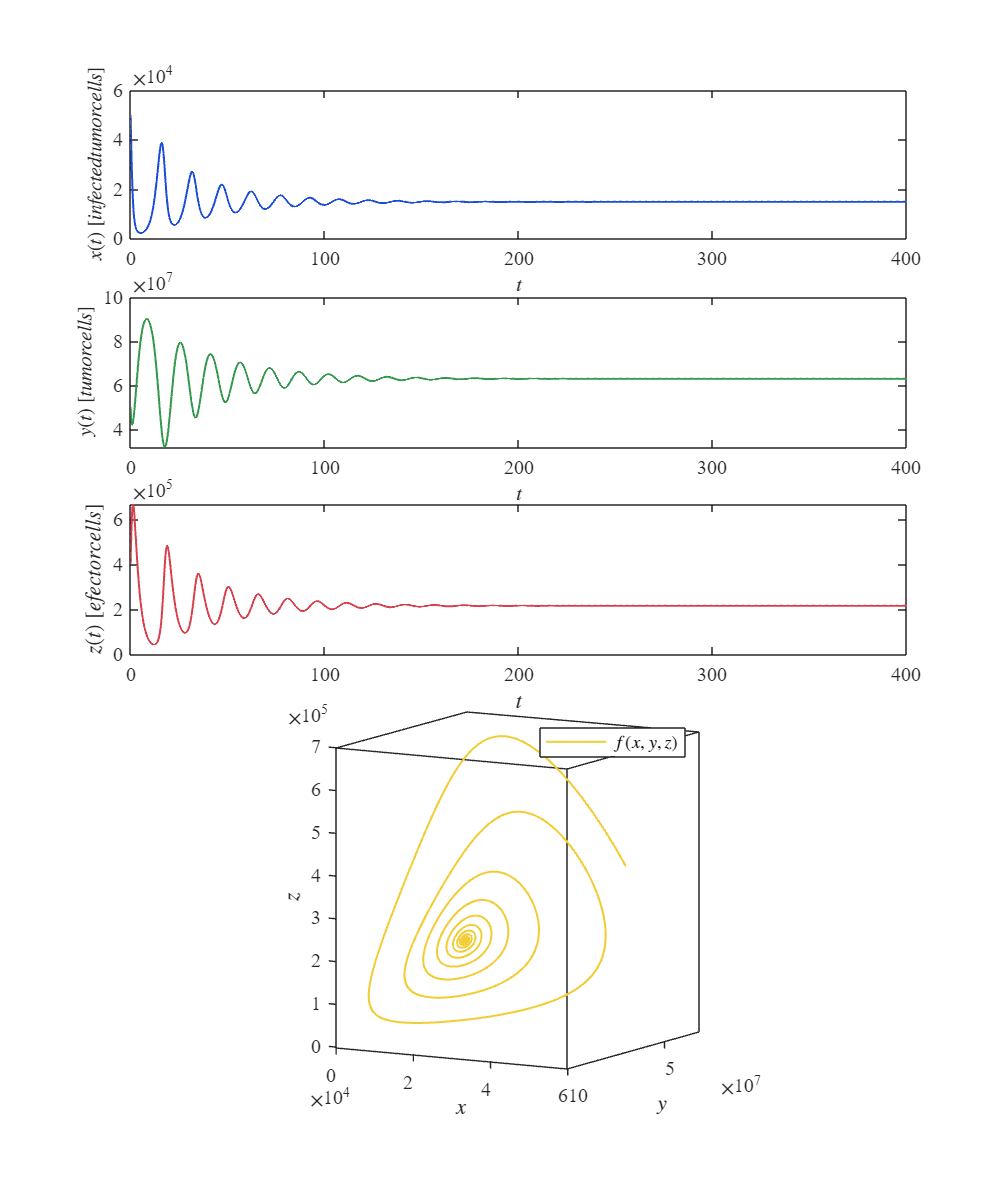

%Datos de la simulación
clc; clear; close all; warning('off','all')
xmax = 1E5; ymax = 1E8; zmax = 1E6;

b1 = 1/xmax; a12 = 0.5/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax; 
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4; 
P = [r1,b1,a13,r2,b2,a21,r3,a31,d3];
rhoi = 0;
dt = 1E-1;
x0 = 0.5*xmax; y0 = 0.5*ymax; z0 = 0.4*zmax;
tend = 400;
[t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs(t,x,y,z);

## Equilibrium points and Jacobian matrix of the system

clear
syms x y z r1 b1 a12 a13 r2 b2 a21 r3 a31 d3 rhoi

dx = r1*x*(1-b1*x)-a12*x*y-a13*x*z;
dy = r2*y*(1-b2*y)-a21*x*y;
dz = (r3-a31)*x*z-d3*z+rhoi;
J = jacobian([dx,dy,dz],[x,y,z]); disp(J)

$$\left(\begin{array}{ccc} -a_{12}\,y-a_{13}\,z-r_{1}\,\left(b_{1}\,x-1\right)-b_{1}\,r_{1}\,x & -a_{12}\,x & -a_{13}\,x\\ -a_{21}\,y & -a_{21}\,x-r_{2}\,\left(b_{2}\,y-1\right)-b_{2}\,r_{2}\,y & 0\\ -z\,\left(a_{31}-r_{3}\right) & 0 & -d_{3}-x\,\left(a_{31}-r_{3}\right) \end{array}\right)$$


dx = r1*x*(1-b1*x)-a12*x*y-a13*x*z == 0;
dy = r2*y*(1-b2*y)-a21*x*y == 0;
dz = (r3-a31)*x*z-d3*z+rhoi == 0;
equilibria = solve([dx,dy,dz],[x,y,z]);

for i = 1:6
    xe(i,1) = simplify(equilibria.x(i));
    ye(i,1) = simplify(equilibria.y(i));
    ze(i,1) = simplify(equilibria.z(i));
    
    fprintf(['Equilibrium points of the system: ', num2str(i),'\n'])
    fprintf(['x',num2str(i),' = ',char(xe(i,1)),'\n']);
    fprintf(['y',num2str(i),' = ',char(ye(i,1)),'\n']);
    fprintf(['z',num2str(i),' = ',char(ze(i,1)),'\n']);
end

Equilibrium points of the system: 1


x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3))


y1 = 0


z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3))


Equilibrium points of the system: 2


x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))


Equilibrium points of the system: 3


x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))


Equilibrium points of the system: 4


x4 = 0


y4 = 1/b2


z4 = rhoi/d3


Equilibrium points of the system: 5


x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3))


y5 = 0


z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3))


Equilibrium points of the system: 6


x6 = 0


y6 = 0


z6 = rhoi/d3


### Equilibrium points of the system without treatment [normalized]

clear
a12i = [1,0.9,0.8,0.75,0.5]; 
r1 = 1; b1 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21= 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
rhoi = 0;

for i = 1:numel(a12i)
    
    a12 = a12i(i);

    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));
    
    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));
    
    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));
    
    x4 = 0;
    y4 = 1/b2;
    z4 = rhoi/d3;
     
    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));
    
    x6 = 0;
    y6 = 0;
    z6 = rhoi/d3;

    xe = [x1;x2;x3;x4;x5;x6]; ye = [y1;y2;y3;y4;y5;y6]; ze = [z1;z2;z3;z4;z5;z6];

    Eqs = array2table([xe,ye,ze], 'VariableNames', {'x*','y*','z*'});
    fprintf(['Equilibrium points with a12 = : ', num2str(a12),'\n']);
    fprintf(['Treatment rhoi =  ', num2str(rhoi),'\n']);
    disp(Eqs)
end

Equilibrium points with a12 = : 1


Treatment rhoi =  0


        x*           y*           z*     
    ___________    _______    ___________

        0.14815          0        0.34074
        0.14815    0.62963       0.088889
    -4.5688e-17          1    -5.4826e-17
              0          1              0
              1          0     2.4672e-17
              0          0              0



Equilibrium points with a12 = : 0.9


Treatment rhoi =  0


      x*         y*           z*     
    _______    _______    ___________

    0.14815          0        0.34074
    0.14815    0.62963        0.11407
      -0.08        1.2    -5.4826e-17
          0          1              0
          1          0     2.4672e-17
          0          0              0



Equilibrium points with a12 = : 0.8


Treatment rhoi =  0


      x*         y*           z*     
    _______    _______    ___________

    0.14815          0        0.34074
    0.14815    0.62963        0.13926
       -0.2        1.5    -1.3706e-16
          0          1              0
          1          0     2.4672e-17
          0          0              0



Equilibrium points with a12 = : 0.75


Treatment rhoi =  0


       x*         y*           z*    
    ________    _______    __________

     0.14815          0       0.34074
     0.14815    0.62963       0.15185
    -0.28571     1.7143    1.3706e-16
           0          1             0
           1          0    2.4672e-17
           0          0             0



Equilibrium points with a12 = : 0.5


Treatment rhoi =  0


      x*         y*           z*    
    _______    _______    __________

    0.14815          0       0.34074
    0.14815    0.62963       0.21481
         -2          6             0
          0          1             0
          1          0    2.4672e-17
          0          0             0



### Equilibrium points of the system with treatment [normalized]

clear
a12i = [1,0.9,0.8,0.75,0.5]; 
r1 = 1; b1 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21= 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
rhoi = 1.1*d3*r1/a13;

for i = 1:numel(a12i)
    
    a12 = a12i(i);

    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));
    
    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));
    
    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));
    
    x4 = 0;
    y4 = 1/b2;
    z4 = rhoi/d3;
     
    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));
    
    x6 = 0;
    y6 = 0;
    z6 = rhoi/d3;

    xe = [x1;x2;x3;x4;x5;x6]; ye = [y1;y2;y3;y4;y5;y6]; ze = [z1;z2;z3;z4;z5;z6];

    Eqs = array2table([xe,ye,ze], 'VariableNames', {'x*','y*','z*'});
    fprintf(['Equilibrium points with a12 = : ', num2str(a12),'\n']);
    fprintf(['Treatment rhoi =  ', num2str(rhoi),'\n']);
    disp(Eqs)
end

Equilibrium points with a12 = : 1


Treatment rhoi =  0.176


            x*                   y*                   z*        
    __________________    ________________    __________________

    -0.012761+0i                0+0i             0.4051+0i      
     0.074074+0.32118i    0.81481-0.80294i     0.044444+0.19271i
     0.074074-0.32118i    0.81481+0.80294i     0.044444-0.19271i
            0+0i                1+0i               0.44+0i      
       1.1609+0i                0+0i          -0.064364+0i      
            0+0i                0+0i               0.44+0i      



Equilibrium points with a12 = : 0.9


Treatment rhoi =  0.176


            x*                   y*                   z*        
    __________________    ________________    __________________

    -0.012761+0i                0+0i             0.4051+0i      
     0.034074+0.34257i    0.91481-0.85644i     0.057037+0.17129i
     0.034074-0.34257i    0.91481+0.85644i     0.057037-0.17129i
            0+0i                1+0i               0.44+0i      
       1.1609+0i                0+0i          -0.064364+0i      
            0+0i                0+0i               0.44+0i      



Equilibrium points with a12 = : 0.8


Treatment rhoi =  0.176


            x*                  y*                   z*        
    __________________    _______________    __________________

    -0.012761+0i               0+0i             0.4051+0i      
    -0.025926+0.36423i    1.0648-0.91057i      0.06963+0.14569i
    -0.025926-0.36423i    1.0648+0.91057i      0.06963-0.14569i
            0+0i               1+0i               0.44+0i      
       1.1609+0i               0+0i          -0.064364+0i      
            0+0i               0+0i               0.44+0i      



Equilibrium points with a12 = : 0.75


Treatment rhoi =  0.176


            x*                  y*                  z*        
    __________________    ______________    __________________

    -0.012761+0i              0+0i             0.4051+0i      
    -0.068783+0.37307i    1.172-0.93269i     0.075926+0.13058i
    -0.068783-0.37307i    1.172+0.93269i     0.075926-0.13058i
            0+0i              1+0i               0.44+0i      
       1.1609+0i              0+0i          -0.064364+0i      
            0+0i              0+0i               0.44+0i      



Equilibrium points with a12 = : 0.5


Treatment rhoi =  0.176


       x*          y*         z*    
    _________    ______    _________

    -0.012761         0       0.4051
     -0.21756    1.5439      0.17824
      -1.6343    5.0857     0.036571
            0         1         0.44
       1.1609         0    -0.064364
            0         0         0.44



## Equilibrium point of the system with treatment [normalized]

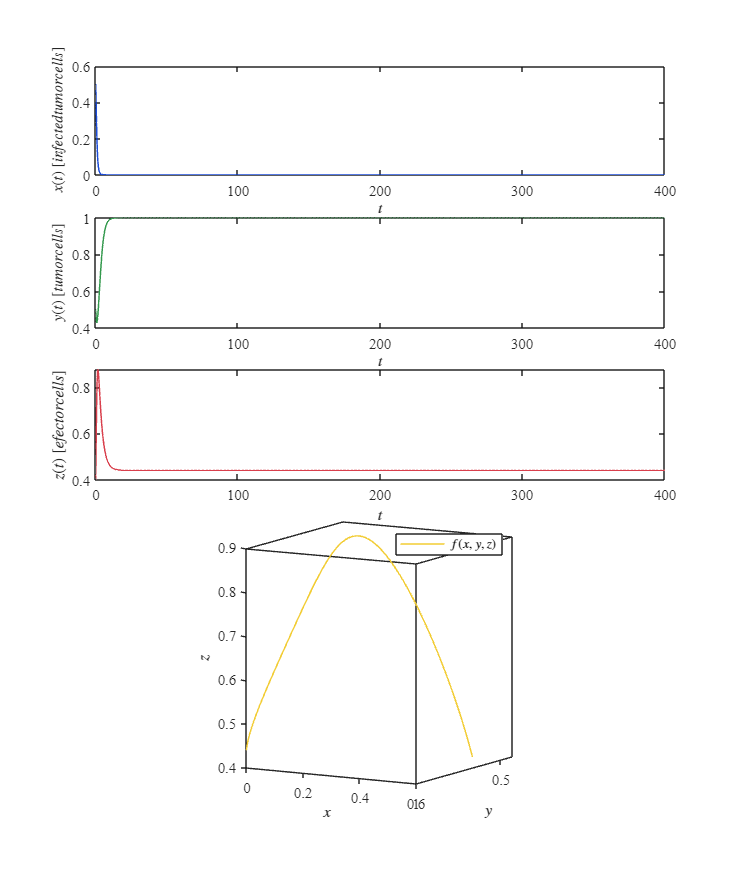

r1 = 1; b1 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21= 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
P = [r1,b1,a13,r2,b2,a21,r3,a31,d3];
a12 = [1,0.9,0.8,0.75,0.5]; 
rhoi =  1.1*d3*r1/a13;
dt = 1E-2; 
tend = [1500,400,600,600,500,100];
x0 = [0.555,0.254781,0.2,0.4,0.5]; 
y0 = [0.148,0.115167,0.6,0.2,0.5]; 
z0 = [0.172,0.600527,0.1,0.4,0.4];
i = 5;
[t,x,y,z] = system(x0(i),y0(i),z0(i),P,a12(i),rhoi,dt,tend(i));
plotEDOs(t,x,y,z);

## Selected system

### Equilibrium points of selected system without treatment [No-normalized]

clear
xmax = 1E5; ymax = 1E8; zmax = 1E6;

b1 = 1/xmax; a12 = 0.5/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax; 
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4; 
rhoi = 0;

x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
y1 = 0;
z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

x4 = 0;
y4 = 1/b2;
z4 = rhoi/d3;
 
x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
y5 = 0;
z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

x6 = 0;
y6 = 0;
z6 = rhoi/d3;

x = [x1;x2;x3;x4;x5;x6]; y = [y1;y2;y3;y4;y5;y6]; z = [z1;z2;z3;z4;z5;z6];

fprintf(['Equilibrium points with a12 = : ', num2str(a12),'\n']);

Equilibrium points with a12 = : 5e-09


fprintf(['Treatment rhoi =  ', num2str(rhoi),'\n']);

Treatment rhoi =  0



L = zeros(3,3);
for i = 1:length(x)
    J = [- a12*y(i) - a13*z(i) - r1*(b1*x(i) - 1) - b1*r1*x(i),     -a12*x(i),                                -a13*x(i); 
        -a21*y(i),                                         - a21*x(i) - r2*(b2*y(i) - 1) - b2*r2*y(i),     0; 
        -z(i)*(a31 - r3),                                  0,                                     - d3 - x(i)*(a31 - r3)];

    L(i,:) = eig(J);
end
Lambda1 = L(:,1); Lambda2 = L(:,2); Lambda3 = L(:,3);

Results = table(x,y,z,Lambda1,Lambda2,Lambda3);
disp(Results)

      x           y              z              Lambda1               Lambda2          Lambda3
    ______    __________    ___________    __________________    __________________    _______

     14815             0     3.4074e+05    -0.074074+0.57901i    -0.074074-0.57901i    0.37778
     14815    6.2963e+07     2.1481e+05    -0.029162+0.41557i    -0.029162-0.41557i    -0.4676
    -2e+05         6e+08     5.8434e-11         -0.8+1.077i           -0.8-1.077i         -5.8
         0         1e+08              0         -0.6+0i                0.5+0i             -0.4
     1e+05             0    -1.2549e-11           -1+0i                2.3+0i             -0.9
         0             0              0         -0.4+0i                0.6+0i                1



### Equilibrium points of selected system with treatment [No-normalized]

clear
xmax = 1E5; ymax = 1E8; zmax = 1E6;

b1 = 1/xmax; a12 = 0.5/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax; 
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4; 
rhoi = 1.1*d3*r1/a13;

x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
y1 = 0;
z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

x4 = 0;
y4 = 1/b2;
z4 = rhoi/d3;
 
x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
y5 = 0;
z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

x6 = 0;
y6 = 0;
z6 = rhoi/d3;

x = [x1;x2;x3;x4;x5;x6]; y = [y1;y2;y3;y4;y5;y6]; z = [z1;z2;z3;z4;z5;z6];

fprintf(['Equilibrium points with a12 = : ', num2str(a12),'\n']);

Equilibrium points with a12 = : 5e-09


fprintf(['Treatment rhoi =  ', num2str(rhoi),'\n']);

Treatment rhoi =  176000



L = zeros(3,3);
for i = 1:length(x)
    J = [- a12*y(i) - a13*z(i) - r1*(b1*x(i) - 1) - b1*r1*x(i),     -a12*x(i),                                -a13*x(i); 
        -a21*y(i),                                         - a21*x(i) - r2*(b2*y(i) - 1) - b2*r2*y(i),     0; 
        -z(i)*(a31 - r3),                                  0,                                     - d3 - x(i)*(a31 - r3)];

    L(i,:) = eig(J);
end
Lambda1 = L(:,1); Lambda2 = L(:,2); Lambda3 = L(:,3);

Results = table(x,y,z,Lambda1,Lambda2,Lambda3);
disp(Results)

         x             y             z              Lambda1              Lambda2         Lambda3
    ___________    __________    __________    _________________    _________________    _______

        -1276.1             0     4.051e+05    0.080522+0i          -0.50222+0i          0.61914
         -21756    1.5439e+08    1.7824e+05     0.21453+0i          -0.83566+0i          -1.0751
    -1.6343e+05    5.0857e+08         36571    -0.68829+0.71338i    -0.68829-0.71338i    -4.8531
              0         1e+08       4.4e+05        -0.4+0i              -0.6+0i             -0.6
     1.1609e+05             0        -64364     -1.2863+0i            2.8599+0i          -1.1414
              0             0       4.4e+05        -0.4+0i              -0.1+0i              0.6



## Equilibrium point of selected system with treatment [No-normalized]

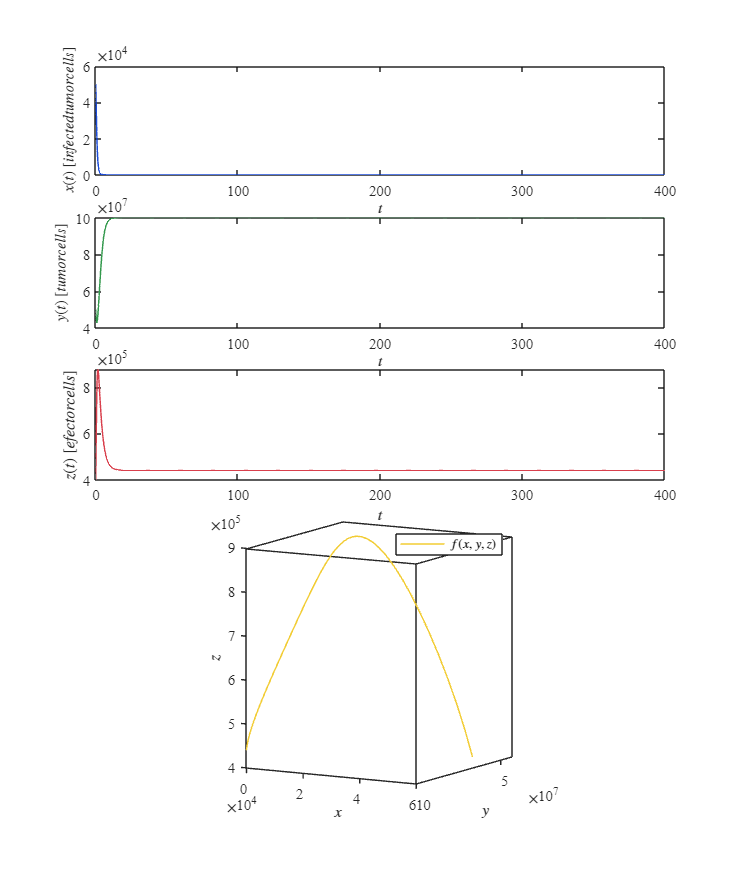

xmax = 1E5; ymax = 1E8; zmax = 1E6;

b1 = 1/xmax; a12 = 0.5/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax; 
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4; 
P = [r1,b1,a13,r2,b2,a21,r3,a31,d3];
rhoi = 1.1*d3*r1/a13;
dt = 1E-1;
x0 = 0.5*xmax; y0 = 0.5*ymax; z0 = 0.4*zmax;
tend = [1500,400,600,600,500,100];
[t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend(5));
plotEDOs(t,x,y,z);

## Functions

function [t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend)
    r1 = P(1); b1 = P(2); a13 = P(3);
    r2 = P(4); b2 = P(5); a21= P(6);
    r3 = P(7); a31 = P(8); d3 = P(9);

    t = (0:dt:tend)';
    n = round(tend/dt);
    x = zeros(length(t),1); x(1) = x0;
    y = zeros(length(t),1); y(1) = y0;
    z = zeros(length(t),1); z(1) = z0;

    for i = 1:n
        [fx,fy,fz] = f(x(i),y(i),z(i));
        xn = x(i) +fx*dt;
        yn = y(i) +fy*dt;
        zn = z(i) +fz*dt;

        [fxn,fyn,fzn] = f(xn,yn,zn);
        x(i+1) = x(i) + (fx +fxn)*dt/2;
        y(i+1) = y(i) + (fy +fyn)*dt/2;
        z(i+1) = z(i) + (fz +fzn)*dt/2;
    end

    function [dx,dy,dz] = f(x,y,z)
        dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z;
        dy = r2*y*(1 - b2*y) - a21*x*y;
        dz = (r3 - a31)*x*z - d3*z + rhoi;
    end 
end

### Soluciones y trayectorias

function plotEDOs(t,x,y,z)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,25,30])

    % tend = [1500,400,600,600,500,400];
    % i = 6;
    c1 = [0.11, 0.30, 0.85]; c2 = [0.20, 0.60, 0.30];
    c3 = [0.85, 0.25, 0.30]; c4 = [0.95, 0.80, 0.20]; 
    m1 = [0.29, 0.00, 0.51]; m2 = [0.60, 0.20, 0.80];
    m3 = [0.73, 0.33, 0.83];

    subplot(5,4,[1,4])
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',c1)
    xlabel('$t$','Interpreter','latex')
    ylabel('$x(t)$ $[infected tumor cells]$','Interpreter','latex')
    % xlim([0 tend(i)]); xticks(0:tend(i)/10:tend(i))
    xlim([0 400]); xticks(0:100:400)
    % ylim([0 1E5]); yticks(0:1E1:1E5)

    subplot(5,4,[5,8])
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',c2)
    xlabel('$t$','Interpreter','latex')
    ylabel('$y(t)$ $[tumor cells]$','Interpreter','latex')
    % xlim([0 tend(i)]); xticks(0:tend(i)/10:tend(i))
    xlim([0 400]); xticks(0:100:400)
    % ylim([0 1E8]); yticks(0:1E1:1E8)
    
    subplot(5,4,[9,12])
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,z,'-','LineWidth',1,'Color',c3)
    xlabel('$t$','Interpreter','latex')
    ylabel('$z(t)$ $[efector cells]$','Interpreter','latex')
    % xlim([0 tend(i)]); xticks(0:tend(i)/10:tend(i))
    xlim([0 400]); xticks(0:100:400)
    % ylim([0 1E6]); yticks(0:1E1:1E6)

    subplot(5,4,[14,19])
    set(gca,'FontName','Times New Roman', 'FontSize', 10)
    hold on; box on; grid off;
    plot3(x,y,z,'-','LineWidth',1,'Color',c4)
    xlabel('$x$','Interpreter','latex')
    ylabel('$y$','Interpreter','latex')
    zlabel('$z$','Interpreter','latex')
    L = legend('$f(x,y,z)$');
    set(L,'Interpreter','latex','Location','northeast','Box','on')
    % xlim([0 1]); xticks(0:0.2:1)
    % ylim([0 1]); yticks(0:0.2:1)
    % zlim([0 1]); zticks(0:0.2:1)
    view(3)
    view([-29.61 -8.05])
end